# Generalized Geometry Projection

Author Simone Coniglio, 12/09/2019

This is an introduction to a Matlab implementation of Generalized Geometry Projection approach for topology optimization.

In this approach geometric primitives are projected on a Finite Element Mesh and assembled together to build the solution. 

## Problem set-up

In this section of the Matlab code we define several **parameters** needed for the **Generalized Geometry Projection**.

%-------------------------------------------------------------
%    This is the file GGP.mlx you can redistribute it and/or
%    modify it under the terms of the GNU General Public License as 
%    published by the Free Software Foundation; either version 3 of 
%    the License, or (at your option) any later version.
%    
%    This code is distributed in the hope that it will be useful,
%    but WITHOUT ANY WARRANTY; without even the implied warranty of
%    MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
%    GNU General Public License for more details.
%    
%    You should have received a copy of the GNU General Public License
%    (file COPYING) along with this file.  If not, see 
%    <http://www.gnu.org/licenses/>.
%
%    Version Nov 2019.
%    Simone Coniglio <simone.coniglio@airbus.com>
%    Propulsion Airframe Stress Transverse,
%    31300 Toulouse, France.
%
% GGP parameters
stopping_criteria='change'; %stopping criteria of the optimization algorithm either change or KKT norm
nelx=60;nely=30; 
BC='Short_Cantilever';%L-shape %Short_Cantilever%MBB
p.method='GP';%MMC%MNA %GP this change the function employed for the evaluation of local volume fraction
q=1;%q=1
p.zp=1 ;% parameter for p-norm/mean regularization
p.alp=1; %parameter for MMC
p.epsi=0.866;% parameter for MMC
p.bet=1e-3; %parameter for MMC
p.deltamin=1e-6; %parameter for GP
p.r=.5;%parameter for GP
minh=1;% minimal bar thickness
p.sigma=1;%parameter for MNA
p.gammav=1;%parameter for GP
p.gammac=3;%parameter for GP
p.penalty=3;%parameter for MNA
p.aggregation='KSl'; %parameter for the aggregation function to be used
% IE= Induced Exponential % KS= KS function %KSl= lowerbound KS function
% p-norm %p-mean
p.ka=10; % parameter for the aggregation constant
p.saturation=true; % switch for saturation
ncx=1; % number of components in the x direction
ncy=1; % number of components in the y direction
Ngp=2; % number of Gauss point per sampling window
R=0.5; % radius of the sampling window (infty norm)
initial_d=0.5; % initial mass variable adopted for MNA and GP

Generate a **folder** and a prefix to save images **optimization history**:

rs=replace(num2str(R,'%3.2f'),'.','_');
folder_name=['Optimization_history_',BC,p.method,'nelx_',num2str(nelx),...
    'nely_',num2str(nely),'_R_',rs,'_Ngp_',num2str(Ngp),'_SC_',stopping_criteria];
image_prefix=[BC,p.method,'nelx_',num2str(nelx),'nely_',num2str(nely),'_R_',rs,'_Ngp_',num2str(Ngp)];
mkdir(folder_name)

Path=[folder_name,'/'];

Define **Material properties**:

% MATERIAL PROPERTIES
p.E0 = 1;
p.Emin = 1e-6;
nu = 0.3;

Prepare **finite element analysis**

% PREPARE FINITE ELEMENT ANALYSIS
A11 = [12  3 -6 -3;  3 12  3  0; -6  3 12 -3; -3  0 -3 12];
A12 = [-6 -3  0  3; -3 -6 -3 -6;  0 -3 -6  3;  3 -6  3 -6];
B11 = [-4  3 -2  9;  3 -4 -9  4; -2 -9 -4 -3;  9  4 -3 -4];
B12 = [ 2 -3  4 -9; -3  2  9 -2;  4  9  2  3; -9 -2  3  2];
KE = 1/(1-nu^2)/24*([A11 A12;A12' A11]+nu*[B11 B12;B12' B11]);
nodenrs = reshape(1:(1+nelx)*(1+nely),1+nely,1+nelx);
edofVec = reshape(2*nodenrs(1:end-1,1:end-1)+1,nelx*nely,1);
edofMat = repmat(edofVec,1,8)+repmat([0 1 2*nely+[2 3 0 1] -2 -1],nelx*nely,1);
iK = reshape(kron(edofMat,ones(8,1))',64*nelx*nely,1);
jK = reshape(kron(edofMat,ones(1,8))',64*nelx*nely,1);
U = zeros(2*(nely+1)*(nelx+1),1);
%define the nodal coordinates
[Yy,Xx]=find(nodenrs);
Yy=nely+1-Yy;
Xx=Xx-1;
% Element connectivity
enodeMat=edofMat(:,[2,4,6,8])/2;
% DEFINE LOADS AND SUPPORTS 
switch BC
    case 'MBB'
        excitation_node=1;excitation_direction=2;
        amplitude=-1;
        F = sparse(2*(excitation_node-1)+excitation_direction,1,amplitude,2*(nely+1)*(nelx+1),1);
        fixednodes=[find(Xx==min(Xx));(nelx+1)*(nely+1)];fixed_dir=[ones(nely+1,1);2];
        fixeddofs=2*(fixednodes-1)+fixed_dir;
        emptyelts=[]; fullelts = [];
    case 'Short_Cantilever'
        excitation_node=find((Xx==max(Xx))&(Yy==fix(0.5*min(Yy)+0.5*max(Yy))));excitation_direction=2;
        amplitude=-1;
        F = sparse(2*(excitation_node-1)+excitation_direction,1,amplitude,2*(nely+1)*(nelx+1),1);
        fixednodes=repmat(find(Xx==min(Xx)),2,1);fixed_dir=[ones(nely+1,1);2*ones(nely+1,1)];
        fixeddofs=2*(fixednodes-1)+fixed_dir(:);
        emptyelts=[]; fullelts = [];
    case 'L-shape'
        excitation_node=find((Xx==max(Xx))&(Yy==fix(0.5*min(Yy)+0.5*max(Yy))));excitation_direction=2;
        amplitude=-1;
        F = sparse(2*(excitation_node-1)+excitation_direction,1,amplitude,2*(nely+1)*(nelx+1),1);
        fixednodes=repmat(find(Yy==max(Yy)),2,1);fixed_dir=[ones(nelx+1,1),2*ones(nelx+1,1)];
        fixeddofs=2*(fixednodes-1)+fixed_dir(:);
        emptyelts=find(xc>=(((max(Xx)+min(Xx))/2))&(yc>=((max(Yy)+min(Yy))/2)));
        fullelts = [];
    otherwise
        error('BC string should be a valid entry: ''MBB'',''L-Shape'',''Short_Cantilever''')
end
alldofs = [1:2*(nely+1)*(nelx+1)];
freedofs = setdiff(alldofs,fixeddofs);

## Prepare the **Generalized Geometry Projection:**

Compute the element centroid coordinates:

xc=mean(Xx(enodeMat'));
yc=mean(Yy(enodeMat'));
centroid_coordinate=[xc(:),yc(:)];

Compute **Gauss point coordinates and weights **in a squared sampling window $[2R\times2R]$ centred in the origin

a=-R;
b=R;
[gpc,wc]=lgwt(Ngp,a,b);
[gpcx,gpcy]=meshgrid(gpc,gpc);
gauss_weight=wc*wc';

Repeat the value ones for each element in the mesh

gpcx=reshape((repmat(gpcx(:),1,size(centroid_coordinate,1)))',[],1);
gpcy=reshape((repmat(gpcy(:),1,size(centroid_coordinate,1)))',[],1);
gauss_weight=reshape((repmat(gauss_weight(:),1,size(centroid_coordinate,1)))',[],1);

translate the sampling window Gauss points of the element centroid coordinates

cc=repmat(centroid_coordinate,Ngp^2,1);
gauss_point=cc+[gpcx,gpcy];

Avoid to evaluate repeated value of sampling window gauss point coordinates:

[ugp,~,idgp]=unique(gauss_point,'rows');

## Initialize design variable vector:

The initial design is composed of couples of crossed components regularly disposed in the mesh. 

xp=linspace(min(Xx),max(Xx),ncx+2);
yp=linspace(min(Yy),max(Yy),ncy+2); 
[xx,yy]=meshgrid(xp,yp);
Xc=repmat(xx(:),2,1); %component center X
Yc=repmat(yy(:),2,1); %component center Y
Lc=2*sqrt((nelx/(ncx+2))^2+(nely/(ncy+2))^2)*ones(size(Xc)); %component length L
Tc=atan2(nely/ncy,nelx/ncx)*[ones(length(Xc)/2,1);-ones(length(Xc)/2,1)];% component orientation angle tetha
hc=2*ones(length(Xc),1); % component h
Mc=initial_d*ones(size(Xc)); % component mass (For MNA and GP)
Xg=reshape([Xc,Yc,Lc,hc,Tc,Mc]',[],1);

## Build upper and lower bounds of the design problem

Xl=min(Xx-1)*ones(size(Xc));Xu=max(Xx+1)*ones(size(Xc));
Yl=min(Yy-1)*ones(size(Xc));Yu=max(Yy+1)*ones(size(Xc));
Ll=0*ones(size(Xc));Lu=sqrt(nelx^2+nely^2)*ones(size(Xc));
hl=minh*ones(size(Xc));hu=sqrt(nelx^2+nely^2)*ones(size(Xc));
Tl=-2*pi*ones(size(Xc));Tu=2*pi*ones(size(Xc));
Ml=0*ones(size(Xc));Mu=ones(size(Xc));
lower_bound=reshape([Xl,Yl,Ll,hl,Tl,Ml]',[],1);
upper_bound=reshape([Xu,Yu,Lu,hu,Tu,Mu]',[],1);

**Scale** the **design variable vector** accordingly  $(X\in[0,1])$:

X=(Xg-lower_bound)./(upper_bound-lower_bound);

## MMA initialization:

loop = 0;
m = 1;
n = length(X(:));
epsimin = 0.0000001;
eeen    = ones(n,1);
eeem    = ones(m,1);
zeron   = zeros(n,1);
zerom   = zeros(m,1);
xval    = X(:);
xold1   = xval;
xold2   = xval;
xmin    = zeron;
xmax    = eeen;
low     = xmin;
upp     = xmax;
C       = 1000*eeem;
d       = 0*eeem;
a0      = 1;
a       = zerom;
outeriter = 0;
maxoutit  = 2000;
kkttol  =0.001;
changetol=0.001;
kktnorm = kkttol+10;
outit = 0;
change=1;

choose the allowable **volfrac:**

volfrac=.4;

Prepare plots and quantity storage:

cvec=zeros(maxoutit,1);
vvec=cvec;ovvec=cvec;gvec=cvec;pvec=cvec;
plot_rate=10;
%initialize variables for plot
tt=0:0.005:(2*pi);tt=repmat(tt,length(Xc),1);
cc=cos(tt);ss=sin(tt);

Initialize the stopping criterion

switch stopping_criteria
    case 'kktnorm'
        stop_cond=outit < maxoutit && kktnorm>kkttol;
    case 'change'
        stop_cond=outit < maxoutit &&change>changetol;
end

## Start the design loop:

 It.:    1 Obj.:4.236e+04 Vol.:  0.074 kktnorm.: 10.001 ch.:  1.000


 It.:    2 Obj.:1.028e+04 Vol.:  0.113 kktnorm.: 84.904 ch.:  0.088


 It.:    3 Obj.:5.624e+03 Vol.:  0.149 kktnorm.: 74.311 ch.:  0.085


 It.:    4 Obj.:2.991e+03 Vol.:  0.183 kktnorm.: 64.682 ch.:  0.079


 It.:    5 Obj.:1.979e+03 Vol.:  0.220 kktnorm.: 55.702 ch.:  0.069


 It.:    6 Obj.:1.513e+03 Vol.:  0.254 kktnorm.: 45.613 ch.:  0.066


 It.:    7 Obj.:1.187e+03 Vol.:  0.282 kktnorm.: 36.972 ch.:  0.063


 It.:    8 Obj.:9.474e+02 Vol.:  0.315 kktnorm.: 30.084 ch.:  0.062


 It.:    9 Obj.:7.933e+02 Vol.:  0.346 kktnorm.: 21.728 ch.:  0.056


 It.:   10 Obj.:6.889e+02 Vol.:  0.370 kktnorm.: 14.059 ch.:  0.049


 It.:   11 Obj.:6.176e+02 Vol.:  0.387 kktnorm.:  8.511 ch.:  0.038


 It.:   12 Obj.:5.764e+02 Vol.:  0.395 kktnorm.:  4.412 ch.:  0.030


 It.:   13 Obj.:5.517e+02 Vol.:  0.398 kktnorm.:  2.943 ch.:  0.026


 It.:   14 Obj.:5.367e+02 Vol.:  0.399 kktnorm.:  2.346 ch.:  0.024


 It.:   15 Obj.:5.244e+02 Vol.:  0.398 kktnorm.:  2.399 ch.:  0.023


 It.:   16 Obj.:5.121e+02 Vol.:  0.400 kktnorm.:  2.078 ch.:  0.024


 It.:   17 Obj.:5.033e+02 Vol.:  0.399 kktnorm.:  2.672 ch.:  0.023


 It.:   18 Obj.:4.927e+02 Vol.:  0.398 kktnorm.:  2.305 ch.:  0.022


 It.:   19 Obj.:4.820e+02 Vol.:  0.399 kktnorm.:  2.097 ch.:  0.022


 It.:   20 Obj.:4.719e+02 Vol.:  0.399 kktnorm.:  2.049 ch.:  0.021


 It.:   21 Obj.:4.621e+02 Vol.:  0.399 kktnorm.:  1.957 ch.:  0.021


 It.:   22 Obj.:4.529e+02 Vol.:  0.399 kktnorm.:  1.972 ch.:  0.021


 It.:   23 Obj.:4.440e+02 Vol.:  0.399 kktnorm.:  1.862 ch.:  0.020


 It.:   24 Obj.:4.354e+02 Vol.:  0.399 kktnorm.:  1.834 ch.:  0.020


 It.:   25 Obj.:4.271e+02 Vol.:  0.399 kktnorm.:  1.883 ch.:  0.020


 It.:   26 Obj.:4.189e+02 Vol.:  0.399 kktnorm.:  1.863 ch.:  0.021


 It.:   27 Obj.:4.106e+02 Vol.:  0.399 kktnorm.:  1.805 ch.:  0.019


 It.:   28 Obj.:4.029e+02 Vol.:  0.399 kktnorm.:  1.998 ch.:  0.019


 It.:   29 Obj.:3.951e+02 Vol.:  0.399 kktnorm.:  1.814 ch.:  0.020


 It.:   30 Obj.:3.874e+02 Vol.:  0.399 kktnorm.:  1.765 ch.:  0.020


 It.:   31 Obj.:3.803e+02 Vol.:  0.399 kktnorm.:  1.766 ch.:  0.020


 It.:   32 Obj.:3.733e+02 Vol.:  0.399 kktnorm.:  1.818 ch.:  0.019


 It.:   33 Obj.:3.666e+02 Vol.:  0.399 kktnorm.:  1.828 ch.:  0.020


 It.:   34 Obj.:3.603e+02 Vol.:  0.399 kktnorm.:  1.885 ch.:  0.019


 It.:   35 Obj.:3.541e+02 Vol.:  0.399 kktnorm.:  1.847 ch.:  0.019


 It.:   36 Obj.:3.479e+02 Vol.:  0.399 kktnorm.:  1.873 ch.:  0.019


 It.:   37 Obj.:3.416e+02 Vol.:  0.399 kktnorm.:  1.904 ch.:  0.019


 It.:   38 Obj.:3.355e+02 Vol.:  0.399 kktnorm.:  1.831 ch.:  0.019


 It.:   39 Obj.:3.293e+02 Vol.:  0.399 kktnorm.:  1.815 ch.:  0.019


 It.:   40 Obj.:3.238e+02 Vol.:  0.399 kktnorm.:  1.761 ch.:  0.019


 It.:   41 Obj.:3.179e+02 Vol.:  0.399 kktnorm.:  1.786 ch.:  0.019


 It.:   42 Obj.:3.118e+02 Vol.:  0.399 kktnorm.:  1.797 ch.:  0.019


 It.:   43 Obj.:3.064e+02 Vol.:  0.399 kktnorm.:  1.763 ch.:  0.019


 It.:   44 Obj.:3.010e+02 Vol.:  0.399 kktnorm.:  1.770 ch.:  0.019


 It.:   45 Obj.:2.957e+02 Vol.:  0.399 kktnorm.:  1.769 ch.:  0.019


 It.:   46 Obj.:2.902e+02 Vol.:  0.399 kktnorm.:  1.792 ch.:  0.020


 It.:   47 Obj.:2.848e+02 Vol.:  0.399 kktnorm.:  1.795 ch.:  0.019


 It.:   48 Obj.:2.796e+02 Vol.:  0.399 kktnorm.:  1.796 ch.:  0.019


 It.:   49 Obj.:2.745e+02 Vol.:  0.399 kktnorm.:  1.791 ch.:  0.019


 It.:   50 Obj.:2.694e+02 Vol.:  0.399 kktnorm.:  1.783 ch.:  0.017


 It.:   51 Obj.:2.642e+02 Vol.:  0.399 kktnorm.:  1.793 ch.:  0.019


 It.:   52 Obj.:2.597e+02 Vol.:  0.399 kktnorm.:  1.704 ch.:  0.015


 It.:   53 Obj.:2.557e+02 Vol.:  0.399 kktnorm.:  1.724 ch.:  0.012


 It.:   54 Obj.:2.516e+02 Vol.:  0.399 kktnorm.:  1.715 ch.:  0.012


 It.:   55 Obj.:2.476e+02 Vol.:  0.399 kktnorm.:  1.725 ch.:  0.012


 It.:   56 Obj.:2.437e+02 Vol.:  0.399 kktnorm.:  1.757 ch.:  0.013


 It.:   57 Obj.:2.399e+02 Vol.:  0.399 kktnorm.:  1.747 ch.:  0.012


 It.:   58 Obj.:2.363e+02 Vol.:  0.399 kktnorm.:  1.746 ch.:  0.011


 It.:   59 Obj.:2.327e+02 Vol.:  0.399 kktnorm.:  1.772 ch.:  0.011


 It.:   60 Obj.:2.291e+02 Vol.:  0.399 kktnorm.:  1.780 ch.:  0.011


 It.:   61 Obj.:2.256e+02 Vol.:  0.399 kktnorm.:  1.754 ch.:  0.012


 It.:   62 Obj.:2.221e+02 Vol.:  0.399 kktnorm.:  1.755 ch.:  0.012


 It.:   63 Obj.:2.190e+02 Vol.:  0.400 kktnorm.:  1.743 ch.:  0.012


 It.:   64 Obj.:2.155e+02 Vol.:  0.400 kktnorm.:  2.534 ch.:  0.012


 It.:   65 Obj.:2.125e+02 Vol.:  0.399 kktnorm.:  2.425 ch.:  0.011


 It.:   66 Obj.:2.094e+02 Vol.:  0.399 kktnorm.:  1.780 ch.:  0.011


 It.:   67 Obj.:2.063e+02 Vol.:  0.399 kktnorm.:  1.776 ch.:  0.011


 It.:   68 Obj.:2.032e+02 Vol.:  0.399 kktnorm.:  1.787 ch.:  0.012


 It.:   69 Obj.:2.002e+02 Vol.:  0.399 kktnorm.:  1.784 ch.:  0.011


 It.:   70 Obj.:1.974e+02 Vol.:  0.399 kktnorm.:  1.769 ch.:  0.011


 It.:   71 Obj.:1.945e+02 Vol.:  0.399 kktnorm.:  1.751 ch.:  0.011


 It.:   72 Obj.:1.917e+02 Vol.:  0.399 kktnorm.:  1.766 ch.:  0.011


 It.:   73 Obj.:1.889e+02 Vol.:  0.399 kktnorm.:  1.774 ch.:  0.011


 It.:   74 Obj.:1.862e+02 Vol.:  0.399 kktnorm.:  1.767 ch.:  0.011


 It.:   75 Obj.:1.835e+02 Vol.:  0.399 kktnorm.:  1.757 ch.:  0.012


 It.:   76 Obj.:1.809e+02 Vol.:  0.399 kktnorm.:  1.758 ch.:  0.011


 It.:   77 Obj.:1.783e+02 Vol.:  0.399 kktnorm.:  1.756 ch.:  0.011


 It.:   78 Obj.:1.757e+02 Vol.:  0.399 kktnorm.:  1.760 ch.:  0.011


 It.:   79 Obj.:1.733e+02 Vol.:  0.399 kktnorm.:  1.748 ch.:  0.011


 It.:   80 Obj.:1.708e+02 Vol.:  0.399 kktnorm.:  1.851 ch.:  0.012


 It.:   81 Obj.:1.683e+02 Vol.:  0.400 kktnorm.:  1.840 ch.:  0.017


 It.:   82 Obj.:1.662e+02 Vol.:  0.399 kktnorm.:  2.123 ch.:  0.012


 It.:   83 Obj.:1.639e+02 Vol.:  0.399 kktnorm.:  1.838 ch.:  0.011


 It.:   84 Obj.:1.617e+02 Vol.:  0.399 kktnorm.:  1.722 ch.:  0.010


 It.:   85 Obj.:1.595e+02 Vol.:  0.399 kktnorm.:  1.726 ch.:  0.010


 It.:   86 Obj.:1.574e+02 Vol.:  0.399 kktnorm.:  1.729 ch.:  0.010


 It.:   87 Obj.:1.553e+02 Vol.:  0.399 kktnorm.:  1.736 ch.:  0.011


 It.:   88 Obj.:1.532e+02 Vol.:  0.399 kktnorm.:  1.769 ch.:  0.011


 It.:   89 Obj.:1.511e+02 Vol.:  0.399 kktnorm.:  1.817 ch.:  0.011


 It.:   90 Obj.:1.491e+02 Vol.:  0.399 kktnorm.:  1.861 ch.:  0.010


 It.:   91 Obj.:1.472e+02 Vol.:  0.399 kktnorm.:  1.869 ch.:  0.010


 It.:   92 Obj.:1.452e+02 Vol.:  0.399 kktnorm.:  1.822 ch.:  0.010


 It.:   93 Obj.:1.434e+02 Vol.:  0.399 kktnorm.:  1.820 ch.:  0.011


 It.:   94 Obj.:1.415e+02 Vol.:  0.399 kktnorm.:  1.803 ch.:  0.012


 It.:   95 Obj.:1.396e+02 Vol.:  0.399 kktnorm.:  1.807 ch.:  0.012


 It.:   96 Obj.:1.379e+02 Vol.:  0.399 kktnorm.:  1.794 ch.:  0.012


 It.:   97 Obj.:1.361e+02 Vol.:  0.399 kktnorm.:  1.765 ch.:  0.013


 It.:   98 Obj.:1.343e+02 Vol.:  0.399 kktnorm.:  1.751 ch.:  0.013


 It.:   99 Obj.:1.326e+02 Vol.:  0.399 kktnorm.:  1.748 ch.:  0.013


 It.:  100 Obj.:1.309e+02 Vol.:  0.399 kktnorm.:  1.735 ch.:  0.014


 It.:  101 Obj.:1.292e+02 Vol.:  0.399 kktnorm.:  1.731 ch.:  0.015


 It.:  102 Obj.:1.275e+02 Vol.:  0.399 kktnorm.:  1.730 ch.:  0.014


 It.:  103 Obj.:1.259e+02 Vol.:  0.399 kktnorm.:  1.759 ch.:  0.020


 It.:  104 Obj.:1.244e+02 Vol.:  0.400 kktnorm.:  2.041 ch.:  0.021


 It.:  105 Obj.:1.228e+02 Vol.:  0.402 kktnorm.:  3.422 ch.:  0.020


 It.:  106 Obj.:1.220e+02 Vol.:  0.398 kktnorm.:  3.934 ch.:  0.018


 It.:  107 Obj.:1.200e+02 Vol.:  0.399 kktnorm.:  3.828 ch.:  0.016


 It.:  108 Obj.:1.185e+02 Vol.:  0.399 kktnorm.:  2.499 ch.:  0.015


 It.:  109 Obj.:1.171e+02 Vol.:  0.399 kktnorm.:  2.233 ch.:  0.015


 It.:  110 Obj.:1.158e+02 Vol.:  0.399 kktnorm.:  2.033 ch.:  0.015


 It.:  111 Obj.:1.145e+02 Vol.:  0.399 kktnorm.:  1.893 ch.:  0.016


 It.:  112 Obj.:1.132e+02 Vol.:  0.399 kktnorm.:  1.761 ch.:  0.016


 It.:  113 Obj.:1.119e+02 Vol.:  0.399 kktnorm.:  1.644 ch.:  0.017


 It.:  114 Obj.:1.106e+02 Vol.:  0.399 kktnorm.:  1.616 ch.:  0.015


 It.:  115 Obj.:1.094e+02 Vol.:  0.399 kktnorm.:  1.613 ch.:  0.016


 It.:  116 Obj.:1.082e+02 Vol.:  0.399 kktnorm.:  1.613 ch.:  0.016


 It.:  117 Obj.:1.070e+02 Vol.:  0.399 kktnorm.:  1.611 ch.:  0.016


 It.:  118 Obj.:1.057e+02 Vol.:  0.399 kktnorm.:  1.604 ch.:  0.016


 It.:  119 Obj.:1.045e+02 Vol.:  0.399 kktnorm.:  1.597 ch.:  0.016


 It.:  120 Obj.:1.033e+02 Vol.:  0.399 kktnorm.:  1.607 ch.:  0.014


 It.:  121 Obj.:1.021e+02 Vol.:  0.399 kktnorm.:  1.621 ch.:  0.014


 It.:  122 Obj.:1.009e+02 Vol.:  0.399 kktnorm.:  1.642 ch.:  0.014


 It.:  123 Obj.:9.973e+01 Vol.:  0.399 kktnorm.:  1.603 ch.:  0.015


 It.:  124 Obj.:9.861e+01 Vol.:  0.399 kktnorm.:  1.700 ch.:  0.015


 It.:  125 Obj.:9.752e+01 Vol.:  0.399 kktnorm.:  1.984 ch.:  0.014


 It.:  126 Obj.:9.648e+01 Vol.:  0.399 kktnorm.:  1.686 ch.:  0.012


 It.:  127 Obj.:9.545e+01 Vol.:  0.399 kktnorm.:  1.674 ch.:  0.012


 It.:  128 Obj.:9.442e+01 Vol.:  0.399 kktnorm.:  1.632 ch.:  0.012


 It.:  129 Obj.:9.340e+01 Vol.:  0.399 kktnorm.:  1.606 ch.:  0.013


 It.:  130 Obj.:9.244e+01 Vol.:  0.399 kktnorm.:  1.541 ch.:  0.014


 It.:  131 Obj.:9.167e+01 Vol.:  0.400 kktnorm.:  1.247 ch.:  0.013


 It.:  132 Obj.:9.118e+01 Vol.:  0.400 kktnorm.:  0.944 ch.:  0.012


 It.:  133 Obj.:9.074e+01 Vol.:  0.400 kktnorm.:  0.907 ch.:  0.012


 It.:  134 Obj.:9.031e+01 Vol.:  0.400 kktnorm.:  0.913 ch.:  0.013


 It.:  135 Obj.:8.989e+01 Vol.:  0.400 kktnorm.:  0.898 ch.:  0.013


 It.:  136 Obj.:8.947e+01 Vol.:  0.400 kktnorm.:  0.890 ch.:  0.013


 It.:  137 Obj.:8.906e+01 Vol.:  0.400 kktnorm.:  0.890 ch.:  0.013


 It.:  138 Obj.:8.866e+01 Vol.:  0.400 kktnorm.:  0.863 ch.:  0.013


 It.:  139 Obj.:8.828e+01 Vol.:  0.400 kktnorm.:  0.868 ch.:  0.013


 It.:  140 Obj.:8.789e+01 Vol.:  0.400 kktnorm.:  1.137 ch.:  0.013


 It.:  141 Obj.:8.750e+01 Vol.:  0.400 kktnorm.:  1.117 ch.:  0.013


 It.:  142 Obj.:8.713e+01 Vol.:  0.400 kktnorm.:  0.863 ch.:  0.014


 It.:  143 Obj.:8.676e+01 Vol.:  0.400 kktnorm.:  0.881 ch.:  0.014


 It.:  144 Obj.:8.640e+01 Vol.:  0.400 kktnorm.:  0.862 ch.:  0.014


 It.:  145 Obj.:8.605e+01 Vol.:  0.400 kktnorm.:  0.860 ch.:  0.014


 It.:  146 Obj.:8.570e+01 Vol.:  0.400 kktnorm.:  0.865 ch.:  0.014


 It.:  147 Obj.:8.535e+01 Vol.:  0.400 kktnorm.:  0.865 ch.:  0.014


 It.:  148 Obj.:8.501e+01 Vol.:  0.400 kktnorm.:  0.863 ch.:  0.014


 It.:  149 Obj.:8.467e+01 Vol.:  0.400 kktnorm.:  0.861 ch.:  0.014


 It.:  150 Obj.:8.434e+01 Vol.:  0.400 kktnorm.:  0.855 ch.:  0.014


 It.:  151 Obj.:8.400e+01 Vol.:  0.400 kktnorm.:  0.845 ch.:  0.014


 It.:  152 Obj.:8.367e+01 Vol.:  0.400 kktnorm.:  0.842 ch.:  0.015


 It.:  153 Obj.:8.335e+01 Vol.:  0.400 kktnorm.:  0.831 ch.:  0.015


 It.:  154 Obj.:8.302e+01 Vol.:  0.400 kktnorm.:  0.811 ch.:  0.016


 It.:  155 Obj.:8.271e+01 Vol.:  0.400 kktnorm.:  0.802 ch.:  0.016


 It.:  156 Obj.:8.240e+01 Vol.:  0.400 kktnorm.:  0.894 ch.:  0.015


 It.:  157 Obj.:8.208e+01 Vol.:  0.400 kktnorm.:  0.834 ch.:  0.015


 It.:  158 Obj.:8.178e+01 Vol.:  0.400 kktnorm.:  0.792 ch.:  0.015


 It.:  159 Obj.:8.148e+01 Vol.:  0.400 kktnorm.:  0.801 ch.:  0.015


 It.:  160 Obj.:8.118e+01 Vol.:  0.400 kktnorm.:  0.773 ch.:  0.015


 It.:  161 Obj.:8.090e+01 Vol.:  0.400 kktnorm.:  0.785 ch.:  0.015


 It.:  162 Obj.:8.061e+01 Vol.:  0.400 kktnorm.:  0.742 ch.:  0.015


 It.:  163 Obj.:8.033e+01 Vol.:  0.400 kktnorm.:  0.808 ch.:  0.015


 It.:  164 Obj.:8.005e+01 Vol.:  0.400 kktnorm.:  0.723 ch.:  0.015


 It.:  165 Obj.:7.978e+01 Vol.:  0.400 kktnorm.:  0.835 ch.:  0.014


 It.:  166 Obj.:7.948e+01 Vol.:  0.400 kktnorm.:  0.725 ch.:  0.015


 It.:  167 Obj.:7.920e+01 Vol.:  0.400 kktnorm.:  1.198 ch.:  0.014


 It.:  168 Obj.:7.895e+01 Vol.:  0.400 kktnorm.:  0.742 ch.:  0.014


 It.:  169 Obj.:7.871e+01 Vol.:  0.400 kktnorm.:  0.741 ch.:  0.014


 It.:  170 Obj.:7.853e+01 Vol.:  0.400 kktnorm.:  0.751 ch.:  0.014


 It.:  171 Obj.:7.838e+01 Vol.:  0.400 kktnorm.:  0.696 ch.:  0.014


 It.:  172 Obj.:7.823e+01 Vol.:  0.400 kktnorm.:  0.714 ch.:  0.013


 It.:  173 Obj.:7.808e+01 Vol.:  0.400 kktnorm.:  0.694 ch.:  0.013


 It.:  174 Obj.:7.792e+01 Vol.:  0.400 kktnorm.:  0.651 ch.:  0.013


 It.:  175 Obj.:7.777e+01 Vol.:  0.400 kktnorm.:  0.599 ch.:  0.010


 It.:  176 Obj.:7.761e+01 Vol.:  0.400 kktnorm.:  0.573 ch.:  0.007


 It.:  177 Obj.:7.746e+01 Vol.:  0.400 kktnorm.:  0.545 ch.:  0.007


 It.:  178 Obj.:7.730e+01 Vol.:  0.400 kktnorm.:  0.565 ch.:  0.007


 It.:  179 Obj.:7.714e+01 Vol.:  0.400 kktnorm.:  0.544 ch.:  0.008


 It.:  180 Obj.:7.699e+01 Vol.:  0.400 kktnorm.:  0.545 ch.:  0.008


 It.:  181 Obj.:7.686e+01 Vol.:  0.400 kktnorm.:  0.536 ch.:  0.007


 It.:  182 Obj.:7.680e+01 Vol.:  0.400 kktnorm.:  0.457 ch.:  0.005


 It.:  183 Obj.:7.675e+01 Vol.:  0.400 kktnorm.:  0.448 ch.:  0.005


 It.:  184 Obj.:7.670e+01 Vol.:  0.400 kktnorm.:  0.294 ch.:  0.006


 It.:  185 Obj.:7.665e+01 Vol.:  0.400 kktnorm.:  0.753 ch.:  0.006


 It.:  186 Obj.:7.661e+01 Vol.:  0.400 kktnorm.:  0.350 ch.:  0.006


 It.:  187 Obj.:7.657e+01 Vol.:  0.400 kktnorm.:  0.457 ch.:  0.005


 It.:  188 Obj.:7.653e+01 Vol.:  0.400 kktnorm.:  0.304 ch.:  0.005


 It.:  189 Obj.:7.649e+01 Vol.:  0.400 kktnorm.:  0.301 ch.:  0.005


 It.:  190 Obj.:7.645e+01 Vol.:  0.400 kktnorm.:  0.298 ch.:  0.005


 It.:  191 Obj.:7.641e+01 Vol.:  0.400 kktnorm.:  0.301 ch.:  0.005


 It.:  192 Obj.:7.637e+01 Vol.:  0.400 kktnorm.:  0.303 ch.:  0.005


 It.:  193 Obj.:7.633e+01 Vol.:  0.400 kktnorm.:  0.294 ch.:  0.005


 It.:  194 Obj.:7.630e+01 Vol.:  0.400 kktnorm.:  0.290 ch.:  0.005


 It.:  195 Obj.:7.626e+01 Vol.:  0.400 kktnorm.:  0.292 ch.:  0.005


 It.:  196 Obj.:7.622e+01 Vol.:  0.400 kktnorm.:  0.279 ch.:  0.005


 It.:  197 Obj.:7.618e+01 Vol.:  0.400 kktnorm.:  0.284 ch.:  0.004


 It.:  198 Obj.:7.614e+01 Vol.:  0.400 kktnorm.:  0.249 ch.:  0.004


 It.:  199 Obj.:7.610e+01 Vol.:  0.400 kktnorm.:  0.307 ch.:  0.004


 It.:  200 Obj.:7.607e+01 Vol.:  0.400 kktnorm.:  0.426 ch.:  0.004


 It.:  201 Obj.:7.603e+01 Vol.:  0.400 kktnorm.:  0.408 ch.:  0.004


 It.:  202 Obj.:7.600e+01 Vol.:  0.400 kktnorm.:  0.314 ch.:  0.004


 It.:  203 Obj.:7.597e+01 Vol.:  0.400 kktnorm.:  0.349 ch.:  0.004


 It.:  204 Obj.:7.594e+01 Vol.:  0.400 kktnorm.:  0.289 ch.:  0.004


 It.:  205 Obj.:7.590e+01 Vol.:  0.400 kktnorm.:  0.292 ch.:  0.004


 It.:  206 Obj.:7.587e+01 Vol.:  0.400 kktnorm.:  0.279 ch.:  0.004


 It.:  207 Obj.:7.584e+01 Vol.:  0.400 kktnorm.:  0.266 ch.:  0.004


 It.:  208 Obj.:7.581e+01 Vol.:  0.400 kktnorm.:  0.248 ch.:  0.004


 It.:  209 Obj.:7.578e+01 Vol.:  0.400 kktnorm.:  0.238 ch.:  0.004


 It.:  210 Obj.:7.575e+01 Vol.:  0.400 kktnorm.:  0.228 ch.:  0.004


 It.:  211 Obj.:7.572e+01 Vol.:  0.400 kktnorm.:  0.221 ch.:  0.004


 It.:  212 Obj.:7.569e+01 Vol.:  0.400 kktnorm.:  0.212 ch.:  0.004


 It.:  213 Obj.:7.566e+01 Vol.:  0.400 kktnorm.:  0.206 ch.:  0.004


 It.:  214 Obj.:7.563e+01 Vol.:  0.400 kktnorm.:  0.201 ch.:  0.004


 It.:  215 Obj.:7.560e+01 Vol.:  0.400 kktnorm.:  0.216 ch.:  0.004


 It.:  216 Obj.:7.556e+01 Vol.:  0.400 kktnorm.:  0.378 ch.:  0.004


 It.:  217 Obj.:7.554e+01 Vol.:  0.400 kktnorm.:  0.695 ch.:  0.004


 It.:  218 Obj.:7.551e+01 Vol.:  0.400 kktnorm.:  0.478 ch.:  0.004


 It.:  219 Obj.:7.548e+01 Vol.:  0.400 kktnorm.:  0.328 ch.:  0.004


 It.:  220 Obj.:7.546e+01 Vol.:  0.400 kktnorm.:  0.318 ch.:  0.004


 It.:  221 Obj.:7.543e+01 Vol.:  0.400 kktnorm.:  0.312 ch.:  0.004


 It.:  222 Obj.:7.540e+01 Vol.:  0.400 kktnorm.:  0.301 ch.:  0.005


 It.:  223 Obj.:7.537e+01 Vol.:  0.400 kktnorm.:  0.287 ch.:  0.005


 It.:  224 Obj.:7.535e+01 Vol.:  0.400 kktnorm.:  0.269 ch.:  0.005


 It.:  225 Obj.:7.532e+01 Vol.:  0.400 kktnorm.:  0.252 ch.:  0.004


 It.:  226 Obj.:7.529e+01 Vol.:  0.400 kktnorm.:  0.238 ch.:  0.004


 It.:  227 Obj.:7.526e+01 Vol.:  0.400 kktnorm.:  0.227 ch.:  0.004


 It.:  228 Obj.:7.524e+01 Vol.:  0.400 kktnorm.:  0.218 ch.:  0.004


 It.:  229 Obj.:7.521e+01 Vol.:  0.400 kktnorm.:  0.212 ch.:  0.004


 It.:  230 Obj.:7.518e+01 Vol.:  0.400 kktnorm.:  0.210 ch.:  0.004


 It.:  231 Obj.:7.516e+01 Vol.:  0.400 kktnorm.:  0.201 ch.:  0.003


 It.:  232 Obj.:7.515e+01 Vol.:  0.400 kktnorm.:  0.198 ch.:  0.002


 It.:  233 Obj.:7.515e+01 Vol.:  0.400 kktnorm.:  0.176 ch.:  0.002


 It.:  234 Obj.:7.514e+01 Vol.:  0.400 kktnorm.:  0.170 ch.:  0.002


 It.:  235 Obj.:7.509e+01 Vol.:  0.400 kktnorm.:  0.151 ch.:  0.005


 It.:  236 Obj.:7.508e+01 Vol.:  0.400 kktnorm.:  0.236 ch.:  0.006


 It.:  237 Obj.:7.512e+01 Vol.:  0.400 kktnorm.:  0.252 ch.:  0.002


 It.:  238 Obj.:7.512e+01 Vol.:  0.400 kktnorm.:  0.273 ch.:  0.002


 It.:  239 Obj.:7.511e+01 Vol.:  0.400 kktnorm.:  0.259 ch.:  0.002


 It.:  240 Obj.:7.511e+01 Vol.:  0.400 kktnorm.:  0.244 ch.:  0.002


 It.:  241 Obj.:7.511e+01 Vol.:  0.400 kktnorm.:  0.232 ch.:  0.001


 It.:  242 Obj.:7.510e+01 Vol.:  0.400 kktnorm.:  0.212 ch.:  0.001


 It.:  243 Obj.:7.510e+01 Vol.:  0.400 kktnorm.:  0.200 ch.:  0.001


 It.:  244 Obj.:7.510e+01 Vol.:  0.400 kktnorm.:  0.183 ch.:  0.002


 It.:  245 Obj.:7.509e+01 Vol.:  0.400 kktnorm.:  0.188 ch.:  0.002


 It.:  246 Obj.:7.509e+01 Vol.:  0.400 kktnorm.:  0.191 ch.:  0.002


 It.:  247 Obj.:7.508e+01 Vol.:  0.400 kktnorm.:  0.199 ch.:  0.002


 It.:  248 Obj.:7.507e+01 Vol.:  0.400 kktnorm.:  0.212 ch.:  0.002


 It.:  249 Obj.:7.507e+01 Vol.:  0.400 kktnorm.:  0.214 ch.:  0.002


 It.:  250 Obj.:7.506e+01 Vol.:  0.400 kktnorm.:  0.244 ch.:  0.001


 It.:  251 Obj.:7.506e+01 Vol.:  0.400 kktnorm.:  0.211 ch.:  0.001


 It.:  252 Obj.:7.506e+01 Vol.:  0.400 kktnorm.:  0.183 ch.:  0.001


 It.:  253 Obj.:7.505e+01 Vol.:  0.400 kktnorm.:  0.214 ch.:  0.001


 It.:  254 Obj.:7.505e+01 Vol.:  0.400 kktnorm.:  0.163 ch.:  0.001


 It.:  255 Obj.:7.505e+01 Vol.:  0.400 kktnorm.:  0.152 ch.:  0.001


 It.:  256 Obj.:7.505e+01 Vol.:  0.400 kktnorm.:  0.169 ch.:  0.001


 It.:  257 Obj.:7.505e+01 Vol.:  0.400 kktnorm.:  0.161 ch.:  0.001


 It.:  258 Obj.:7.504e+01 Vol.:  0.400 kktnorm.:  0.155 ch.:  0.002


 It.:  259 Obj.:7.504e+01 Vol.:  0.400 kktnorm.:  0.151 ch.:  0.002


 It.:  260 Obj.:7.504e+01 Vol.:  0.400 kktnorm.:  0.148 ch.:  0.002


 It.:  261 Obj.:7.504e+01 Vol.:  0.400 kktnorm.:  0.147 ch.:  0.002


 It.:  262 Obj.:7.504e+01 Vol.:  0.400 kktnorm.:  0.142 ch.:  0.002


 It.:  263 Obj.:7.504e+01 Vol.:  0.400 kktnorm.:  0.137 ch.:  0.002


 It.:  264 Obj.:7.504e+01 Vol.:  0.400 kktnorm.:  0.127 ch.:  0.002


 It.:  265 Obj.:7.503e+01 Vol.:  0.400 kktnorm.:  0.118 ch.:  0.002


 It.:  266 Obj.:7.503e+01 Vol.:  0.400 kktnorm.:  0.108 ch.:  0.002


 It.:  267 Obj.:7.503e+01 Vol.:  0.400 kktnorm.:  0.103 ch.:  0.002


 It.:  268 Obj.:7.503e+01 Vol.:  0.400 kktnorm.:  0.095 ch.:  0.002


 It.:  269 Obj.:7.503e+01 Vol.:  0.400 kktnorm.:  0.098 ch.:  0.002


 It.:  270 Obj.:7.503e+01 Vol.:  0.400 kktnorm.:  0.103 ch.:  0.001


 It.:  271 Obj.:7.503e+01 Vol.:  0.400 kktnorm.:  0.172 ch.:  0.001


 It.:  272 Obj.:7.503e+01 Vol.:  0.400 kktnorm.:  0.212 ch.:  0.001


 It.:  273 Obj.:7.503e+01 Vol.:  0.400 kktnorm.:  0.129 ch.:  0.001


 It.:  274 Obj.:7.502e+01 Vol.:  0.400 kktnorm.:  0.184 ch.:  0.001


 It.:  275 Obj.:7.502e+01 Vol.:  0.400 kktnorm.:  0.099 ch.:  0.001


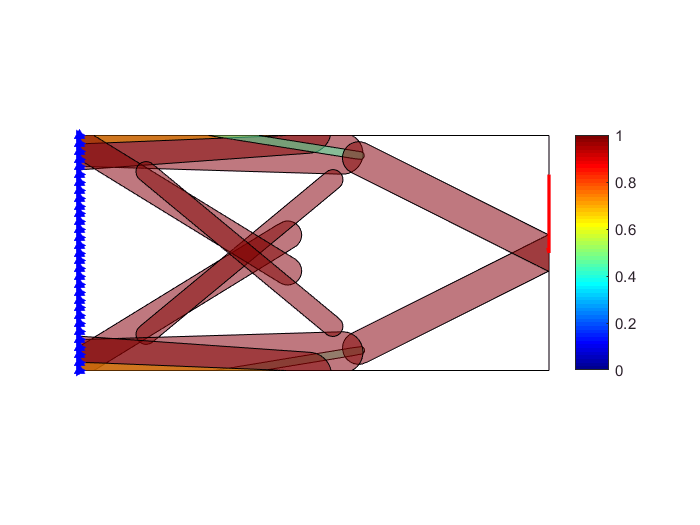

while  stop_cond
    outit   = outit+1;
    outeriter = outeriter+1;
    %Compute the smooth characteristic functions and gradients for each component 
    % on each sampling window Gauss point (Can support GPU)
    [W,dW_dX,dW_dY,dW_dT,dW_dL,dW_dh]=Wgp(ugp(:,1),ugp(:,2),Xg,p);
    %Compute local volume fractions and gradients using generalized projection
    % delta is for densities, deltac for Young modulus
    delta=sum(reshape(W(:,idgp).*repmat(gauss_weight(:)',size(W,1),1),size(W,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(W,1),1),size(W,1),[],Ngp^2),3);
    ddelta_dX=sum(reshape(dW_dX(:,idgp).*repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3);
    ddelta_dY=sum(reshape(dW_dY(:,idgp).*repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3);
    ddelta_dT=sum(reshape(dW_dT(:,idgp).*repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3);
    ddelta_dL=sum(reshape(dW_dL(:,idgp).*repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3);
    ddelta_dh=sum(reshape(dW_dh(:,idgp).*repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3);
    delta_c=sum(reshape(W(:,idgp).^q.*repmat(gauss_weight(:)',size(W,1),1),size(W,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(W,1),1),size(W,1),[],Ngp^2),3);
    ddelta_c_dX=sum(reshape(q*dW_dX(:,idgp).*W(:,idgp).^(q-1).*repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3);
    ddelta_c_dY=sum(reshape(q*dW_dY(:,idgp).*W(:,idgp).^(q-1).*repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3);
    ddelta_c_dT=sum(reshape(q*dW_dT(:,idgp).*W(:,idgp).^(q-1).*repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3);
    ddelta_c_dL=sum(reshape(q*dW_dL(:,idgp).*W(:,idgp).^(q-1).*repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3);
    ddelta_c_dh=sum(reshape(q*dW_dh(:,idgp).*W(:,idgp).^(q-1).*repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3)...
        ./sum(reshape(repmat(gauss_weight(:)',size(dW_dX,1),1),size(dW_dX,1),[],Ngp^2),3);
    % model update 
    % compute young modulus and gradients
    [E,dE,dE_dm]=model_updateM(delta_c,p,X);
    dE_dX=dE.*ddelta_c_dX;
    dE_dY=dE.*ddelta_c_dY;
    dE_dT=dE.*ddelta_c_dT;
    dE_dL=dE.*ddelta_c_dL;
    dE_dh=dE.*ddelta_c_dh;
    E=full(reshape(E(:),nely,nelx));
    %compute densities
    [rho,drho_ddelta,drho_dm]=model_updateV(delta,p,X);
    drho_dX=drho_ddelta.*ddelta_dX;
    drho_dY=drho_ddelta.*ddelta_dY;
    drho_dT=drho_ddelta.*ddelta_dT;
    drho_dL=drho_ddelta.*ddelta_dL;
    drho_dh=drho_ddelta.*ddelta_dh;
    xPhys=full(reshape(rho(:),nely,nelx));
    %Take in account passive elements
    xPhys(emptyelts) = 0;
    xPhys(fullelts) = 1;
    E(emptyelts) = p.Emin;
    E(fullelts) = p.E0;
    % FE-ANALYSIS
    sK = reshape(KE(:)*(E(:)'),64*nelx*nely,1);
    K = sparse(iK,jK,sK); K = (K+K')/2;
    U(freedofs) = K(freedofs,freedofs)\F(freedofs);
    % OBJECTIVE FUNCTION AND SENSITIVITY ANALYSIS
    ce = reshape(sum((U(edofMat)*KE).*U(edofMat),2),nely,nelx);
    c = sum(sum((E).*ce));
    v=mean(xPhys(:));
    dc_dE = -ce;
    dc_dE(emptyelts) = 0;
    dc_dE(fullelts) = 0;
    dc_dX=dE_dX*dc_dE(:);
    dc_dY=dE_dY*dc_dE(:);
    dc_dL=dE_dL*dc_dE(:);
    dc_dh=dE_dh*dc_dE(:);
    dc_dT=dE_dT*dc_dE(:);
    dc_dm=dE_dm*dc_dE(:);
    dc=zeros(size(X));
    dc(1:6:end)=dc_dX;
    dc(2:6:end)=dc_dY;
    dc(3:6:end)=dc_dL;
    dc(4:6:end)=dc_dh;
    dc(5:6:end)=dc_dT;
    dc(6:6:end)=dc_dm;
    dv_dxPhys = ones(nely,nelx)/nelx/nely;
    dv_dxPhys(emptyelts) = 0;
    dv_dxPhys(fullelts) = 0;
    dv_dX=drho_dX*dv_dxPhys(:);
    dv_dY=drho_dY*dv_dxPhys(:);
    dv_dL=drho_dL*dv_dxPhys(:);
    dv_dh=drho_dh*dv_dxPhys(:);
    dv_dT=drho_dT*dv_dxPhys(:);
    dv_dm=drho_dm*dv_dxPhys(:);
    dv=zeros(size(X));
    dv(1:6:end)=dv_dX;
    dv(2:6:end)=dv_dY;
    dv(3:6:end)=dv_dL;
    dv(4:6:end)=dv_dh;
    dv(5:6:end)=dv_dT;
    dv(6:6:end)=dv_dm;
    % store the output for plot
    cvec(outit)=c;vvec(outit)=v;
    %% PRINT RESULTS
    fprintf(' It.:%5i Obj.:%4.3e Vol.:%7.3f kktnorm.:%7.3f ch.:%7.3f\n',outit,c, ...
        mean(xPhys(:)),kktnorm,change);
    % pass scaled objective and constraint function and sensitivities to MMA
    f0val=log(c+1);
    fval=[(v-volfrac)/volfrac]*100;
    df0dx=(dc(:)/(c+1).*(upper_bound(:)-lower_bound(:)));
    dfdx=[dv(:)'/volfrac]*100.*(upper_bound(:)-lower_bound(:))';
    %plot every plot_rate iterations
    if rem(outit,plot_rate)==0
        %convergence plot
        figure(3)
        subplot(2,1,1)
        plot(1:outit,cvec(1:outit),'bo','MarkerFaceColor','b')
        grid on
        hold on
        scatter(outit,c,'k','fill')
        hold off
        text(outit,c,['C =',num2str(c,'%4.2f'),' at iteration ', num2str(outit)],...
            'VerticalAlignment','bottom','HorizontalAlignment','right','FontSize',24,'FontWeight','bold')
         xlabel('iter')
        ylabel('C')
        subplot(2,1,2)
        plot(1:outit,vvec(1:outit)*100,'ro','MarkerFaceColor','r')
        grid on
        hold on
        scatter(outit,mean(xPhys(:))*100,'k','fill')
        hold off
        text(outit,mean(xPhys(:))*100,['V = ',num2str(mean(xPhys(:))*100,'%4.2f'),'% at iteration ', num2str(outit)],...
            'VerticalAlignment','bottom','HorizontalAlignment','right','FontSize',24,'FontWeight','bold')
        xlabel('iter')
        ylabel('V [%]')
        print([Path,image_prefix,'convergence'],'-dpng')
        %% PLOT DENSITIES
        figure(1)
        map=colormap(gray);
        map=map(end:-1:1,:);
        caxis([0 1])
        patchplot2 = patch('Vertices',[Xx,Yy],'Faces',edofMat(:,[2,4,6,8])/2,'FaceVertexCData',(1-xPhys(:))*[1 1 1],...
            'FaceColor','flat','EdgeColor','none'); axis equal; axis off; hold on
        hold on
        fill([min(Xx),max(Xx),max(Xx),min(Xx)],[min(Yy),min(Yy),max(Yy),max(Yy)],'w','FaceAlpha',0.)
        scatter(Xx(fixednodes(fixed_dir==1)),Yy(fixednodes(fixed_dir==1)),'>b','filled')
        scatter(Xx(fixednodes(fixed_dir==2)),Yy(fixednodes(fixed_dir==2)),'^b','filled')
        scal=10;
        quiver(Xx(excitation_node),Yy(excitation_node)+scal*(excitation_direction==2),excitation_direction==1,...
            -(excitation_direction==2), scal,'r','Linewidth',2)
        colormap(map)
        colorbar
        drawnow
        hold off
        axis([min(Xx),max(Xx),min(Yy),max(Yy)])
        print([Path,'density_',num2str(outit-1,'%03d')],'-dpng')
        %% Component Plot
        figure(2)
        Xc=Xg(1:6:end);
        Yc=Xg(2:6:end);
        Lc=Xg(3:6:end);
        hc=Xg(4:6:end);
        Tc=Xg(5:6:end) ;
        Mc=Xg(6:6:end) ;
        C0=repmat(cos(Tc),1,size(cc,2));S0=repmat(sin(Tc),1,size(cc,2));
        xxx=repmat(Xc(:),1,size(cc,2))+cc;
        yyy=repmat(Yc(:),1,size(cc,2))+ss;
        xi=C0.*(xxx-Xc)+S0.*(yyy-Yc);
        Eta=-S0.*(xxx-Xc)+C0.*(yyy-Yc);
        [dd]=norato_bar(xi,Eta,repmat(Lc(:),1,size(cc,2)),repmat(hc(:),1,size(cc,2)));
        xn=repmat(Xc,1,size(cc,2))+dd.*cc;
        yn=repmat(Yc,1,size(cc,2))+dd.*ss;
        tolshow=0.1;
        Shown_compo=find(Mc>tolshow);
        fill([min(Xx),max(Xx),max(Xx),min(Xx)],[min(Yy),min(Yy),max(Yy),max(Yy)],'w','FaceAlpha',0.)
        hold on
        fill(xn(Shown_compo,:)',yn(Shown_compo,:)',Mc(Shown_compo),'FaceAlpha',0.5)
        if strcmp(BC,'L-shape')
            fill([fix((min(Xx)+max(Xx))/2),max(Xx),max(Xx),fix((min(Xx)+max(Xx))/2)],[fix((min(Yy)+max(Yy))/2),...
                fix((min(Yy)+max(Yy))/2),max(Yy),max(Yy)],'w')
        end
        caxis([0,1])
        colormap 'jet'
        axis equal; axis off;
        hold on
        scatter(Xx(fixednodes(fixed_dir==1)),Yy(fixednodes(fixed_dir==1)),'>b','filled')
        scatter(Xx(fixednodes(fixed_dir==2)),Yy(fixednodes(fixed_dir==2)),'^b','filled')
        scal=10;
        quiver(Xx(excitation_node),Yy(excitation_node)+scal*(excitation_direction==2),excitation_direction==1,...
            -(excitation_direction==2),scal,'r','Linewidth',2)
        colorbar
        axis([min(Xx),max(Xx),min(Yy),max(Yy)])
        print([Path,'component_',num2str(outit-1,'%03d')],'-dpng')
        hold off
    end
    %% MMA code optimization
        [X,ymma,zmma,lam,xsi,eta,mu,zet,S,low,upp] = ...
            mmasub(m,n,outeriter,xval,xmin,xmax,xold1,xold2, ...
            f0val,df0dx,fval,dfdx,low,upp,a0,a,C,d);
        xold2 = xold1;
        xold1 = xval;
        xval  = X;
        Xg=lower_bound+(upper_bound-lower_bound).*X;
        change=norm(xval-xold1);
        %% The residual vector of the KKT conditions is calculated:
    [residu,kktnorm,residumax] = ...
        kktcheck(m,n,X,ymma,zmma,lam,xsi,eta,mu,zet,S, ...
        xmin,xmax,df0dx,fval,dfdx,a0,a,C,d);
    % update the stopping criterion
    switch stopping_criteria
        case 'kktnorm'
            stop_cond=outit < maxoutit && kktnorm>kkttol;
        case 'change'
            stop_cond=outit < maxoutit &&change>changetol;
    end
end

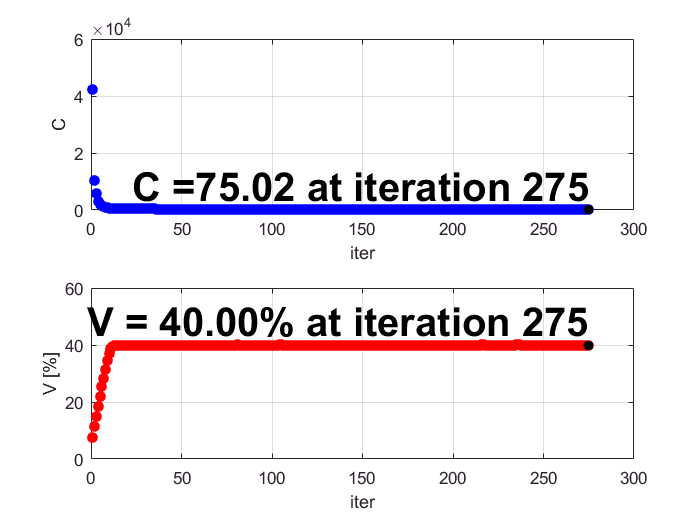

% Make the plot of the solution
% convergence plot
figure(3)
subplot(2,1,1)
plot(1:outit,cvec(1:outit),'bo','MarkerFaceColor','b')
grid on
hold on
scatter(outit,c,'k','fill')
hold off
text(outit,c,['C =',num2str(c,'%4.2f'),' at iteration ', num2str(outit)],...
    'VerticalAlignment','bottom','HorizontalAlignment','right','FontSize',24,'FontWeight','bold')
xlabel('iter')
ylabel('C')
subplot(2,1,2)
plot(1:outit,vvec(1:outit)*100,'ro','MarkerFaceColor','r')
grid on
hold on
scatter(outit,mean(xPhys(:))*100,'k','fill')
hold off
text(outit,mean(xPhys(:))*100,['V = ',num2str(mean(xPhys(:))*100,'%4.2f'),'% at iteration ', num2str(outit)],...
    'VerticalAlignment','bottom','HorizontalAlignment','right','FontSize',24,'FontWeight','bold')
xlabel('iter')
ylabel('V [%]')
print([Path,image_prefix,'convergence'],'-dpng')

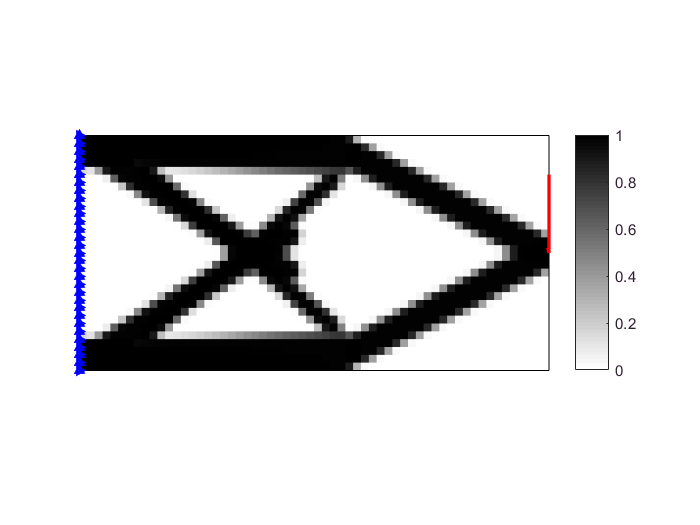

%% PLOT DENSITIES
figure(1)
map=colormap(gray);
map=map(end:-1:1,:);
caxis([0 1])
patchplot2 = patch('Vertices',[Xx,Yy],'Faces',edofMat(:,[2,4,6,8])/2,'FaceVertexCData',(1-xPhys(:))*[1 1 1],...
    'FaceColor','flat','EdgeColor','none'); axis equal; axis off; hold on
hold on
fill([min(Xx),max(Xx),max(Xx),min(Xx)],[min(Yy),min(Yy),max(Yy),max(Yy)],'w','FaceAlpha',0.)
scatter(Xx(fixednodes(fixed_dir==1)),Yy(fixednodes(fixed_dir==1)),'>b','filled')
scatter(Xx(fixednodes(fixed_dir==2)),Yy(fixednodes(fixed_dir==2)),'^b','filled')
scal=10;
quiver(Xx(excitation_node),Yy(excitation_node)+scal*(excitation_direction==2),excitation_direction==1,...
    -(excitation_direction==2), scal,'r','Linewidth',2)
colormap(map)
colorbar
drawnow
hold off
axis([min(Xx),max(Xx),min(Yy),max(Yy)])
print([Path,'density_',num2str(outit-1,'%03d')],'-dpng')

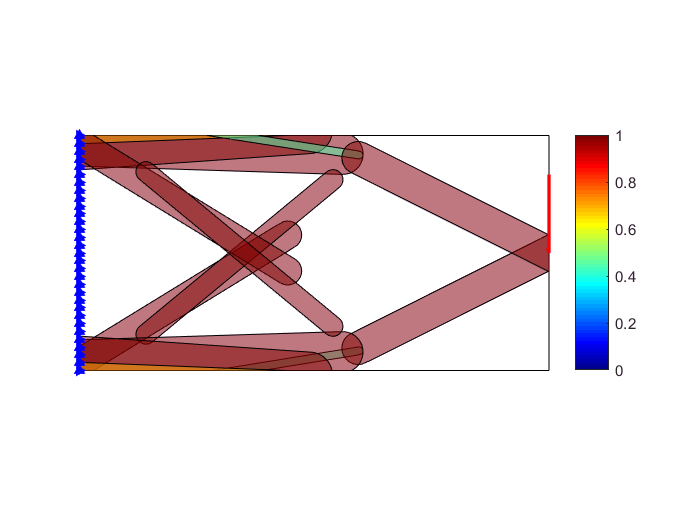

%% Component Plot
figure(2)
Xc=Xg(1:6:end);
Yc=Xg(2:6:end);
Lc=Xg(3:6:end);
hc=Xg(4:6:end);
Tc=Xg(5:6:end) ;
Mc=Xg(6:6:end) ;
C0=repmat(cos(Tc),1,size(cc,2));S0=repmat(sin(Tc),1,size(cc,2));
xxx=repmat(Xc(:),1,size(cc,2))+cc;
yyy=repmat(Yc(:),1,size(cc,2))+ss;
xi=C0.*(xxx-Xc)+S0.*(yyy-Yc);
Eta=-S0.*(xxx-Xc)+C0.*(yyy-Yc);
[dd]=norato_bar(xi,Eta,repmat(Lc(:),1,size(cc,2)),repmat(hc(:),1,size(cc,2)));
xn=repmat(Xc,1,size(cc,2))+dd.*cc;
yn=repmat(Yc,1,size(cc,2))+dd.*ss;
tolshow=0.1;
Shown_compo=find(Mc>tolshow);
fill([min(Xx),max(Xx),max(Xx),min(Xx)],[min(Yy),min(Yy),max(Yy),max(Yy)],'w','FaceAlpha',0.)
hold on
fill(xn(Shown_compo,:)',yn(Shown_compo,:)',Mc(Shown_compo),'FaceAlpha',0.5)
if strcmp(BC,'L-shape')
    fill([fix((min(Xx)+max(Xx))/2),max(Xx),max(Xx),fix((min(Xx)+max(Xx))/2)],...
        [fix((min(Yy)+max(Yy))/2),fix((min(Yy)+max(Yy))/2),max(Yy),max(Yy)],'w')
end
caxis([0,1])
colormap 'jet'
axis equal; axis off;
hold on
scatter(Xx(fixednodes(fixed_dir==1)),Yy(fixednodes(fixed_dir==1)),'>b','filled')
scatter(Xx(fixednodes(fixed_dir==2)),Yy(fixednodes(fixed_dir==2)),'^b','filled')
scal=10;
quiver(Xx(excitation_node),Yy(excitation_node)+scal*(excitation_direction==2),excitation_direction==1,...
    -(excitation_direction==2),scal,'r','Linewidth',2)
colorbar
axis([min(Xx),max(Xx),min(Yy),max(Yy)])
print([Path,'component_',num2str(outit-1,'%03d')],'-dpng')
hold off